# **GAIT RECOGNITION BY ML ANALYSIS ON IMU DATA**

clear ;
close all;
clc
addpath("include");

## **MACROS**

NCOLUMNS = 150;

STARTING_FS = 100;

activities = ["PhaseONE","PhaseTWO","PhaseTHREE", "PhaseFOUR"];

features_avaiable = [
                       "%s mean%s",...                  %01
                       "%s std%s",...                   %02
                       "%s peak%s",...                  %03
                       "%s peak position%s",...         %04
                       "%s mediana%s",...               %05
                       "%s variance%s",...              %06
                       "%s covariance%s",...            %07
                       "%s range%s",...                 %08
                       "%s rms%s",...                   %09
                       "%s mode%s",...                  %10
                       "%s mean or median abs dev%s",...    %11
                       %"%s meanFFT%s"
                       ];

## **DATA IMPORTING**

file1 = readtable("data/record_10-11-21_1st_random.csv", 'VariableNamingRule','preserve');
file2 = readtable("data/record_10-11-21_2nd_linAccZ.csv", 'VariableNamingRule','preserve');

## **CREATION OF THE DATA STRUCTURE**

dataset = {file1, file2};

data = Z_mergeData(dataset);


## RAW DATA ANALYSIS

data_index  = 3;

figure, yyaxis left, plot(data(:,data_index))
yticks([1, 2, 3, 4, 5, 6])

## FREQUENCIES FILTERING

## **CREATION OF STAT_C STRUCTURE**

stat_c = convertToStat(dataset,NCOLUMNS,1);

## MACHINE LEARNING ALGORITHM

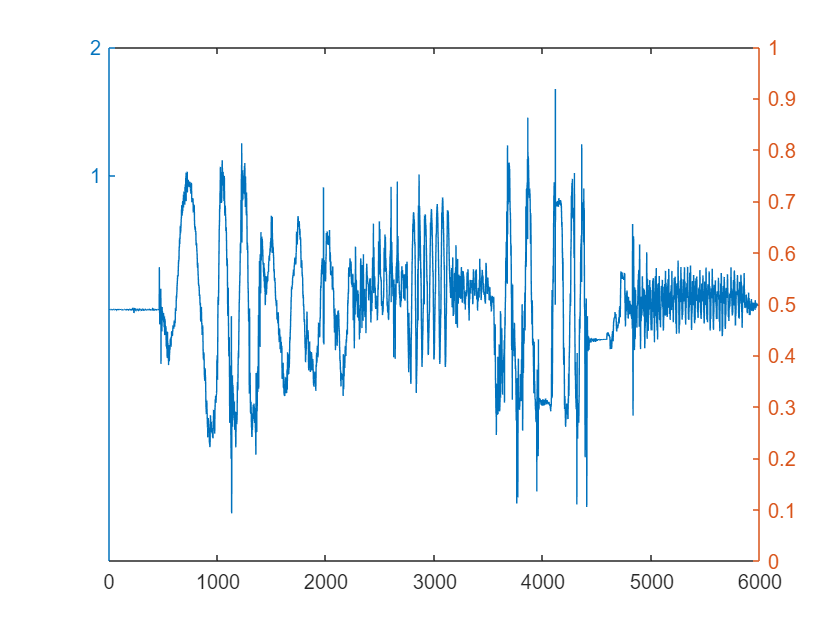

stat = [
    true,... % mean                      %01

    true,... % std                       %02
    true,... % peak                      %03
    true,... % peak position             %04
    true,... % mediana                   %05
    true,... % variance                  %06
    true,... % covariance                %07
    true,... % range                     %08
    true,... % rms                       %09
    true,... % mode                      %10
    true,... % mean or median abs dev    %11
    %true,... % mean FFT                  %12
    ];

features = ExtractSignalFeatures2(stat_c, fs, A, B, length(activities), length(stat_c{1}(1,1,:)), stat);
featT = getFeatureLabels(features,features_avaiable,stat);

[tests,training] = getTrainingMatrix(features,9,stat);
trainingT = getFeatureLabels(training,features_avaiable,stat);

%classificationLearner;



trainedModelImportedHigh = load(['models/highpassTrainedModel.mat']).trainedModel;

remainedpredictions = predict(trainedModelImportedHigh.ClassificationEnsemble, tests(:,1:end-1));
confusionchart(tests(:,end), remainedpredictions)

trainedModelImportedBand = load(['models/bandpassTrainedModel.mat']).trainedModel;
bandpass_tests = load('models/bandpass_tests.mat').tests;
remainedpredictions = predict(trainedModelImportedBand.ClassificationEnsemble, bandpass_tests(:,1:end-1));
confusionchart(bandpass_tests(:,end), remainedpredictions)


## TRAINED MODEL BY USING 80% OF THE DATASET

trainedModelImported = load(['models/11trainedModel_using6_80_025.mat']).trainedModel;

remainedpredictions = predict(trainedModelImported.ClassificationEnsemble, tests(:,1:end-1));
confusionchart(tests(:,end), remainedpredictions)